# 确定质量-时间增长关系 及捕食能力系数

t=1:365;
m0=10;
% J
syms a b;
eqn1 = 40 == a^365+b ;
eqn2 = 10 == a^  0+b ;
[a,b] = solve(eqn1,eqn2,a,b,'real',true);
pm.add = double(a)-1;

m(1:365) = a.^t+b ;
plot(t,m)

% % S
% syms K r b;
% eqn1 = 40 == K/(1+(K-1)*exp(-r*365)) + b;
% eqn2 = 10 == K/(1+(K-1)*exp(-r*  0)) + b;
% [K,r,b] = solve(eqn1,eqn2,K,r,b,'real',true);
% m(1:365) = K/(1+(K-1)*exp(-r*t)) + b ;
% plot([t ],m)


dE(t) = W-Q = pm.add*E(t);
(Q.a(1)+E(1)*pm.add)/E(1) = k_n


k1=1;k2=2;
x=1:365;
y=k1*x-k2*x.^(2/3);
plot(x,y)


i=1:0.01*m2:m2;
pm.kk = [0.1 0.2 0.9 0.8];
min = inf;
for r=0:0.01:0.2
    x1 = 0.1*K - pm.n0+K/(1+(K-1)*exp(-r*0.2*pm.m1));
    x2 = 0.9*K - pm.n0+K/(1+(K-1)*exp(-r*0.8*pm.m1));
    x3 = x1^2 + x2^2;
    if x3<min
        rr = r;
        min = x3;
    end
end
rr = r
m = 1:m2/100:m2;
n = pm.n0+pm.n1./(1+(pm.n1-1)*exp(-rr*m));
plot(m,n)


K = pm.n1;
syms a b K
eqn1 = pm.n0 == K / ( 1 + exp( a-b*(0.0*pm.m1) ) );
eqn2 = 0.1*K == K / ( 1 + exp( a-b*(0.2*pm.m1) ) );
eqn3 = 0.9*K == K / ( 1 + exp( a-b*(0.8*pm.m1) ) );
[pm.a pm.b pm.c]= ((vpasolve(eqn1,eqn2,eqn3,a,b,K)));
A = pm.a == real( pm.a );
pm.a=double(pm.a(A));
pm.b=double(pm.b(A));
K = double (pm.c);
% test K&r
m2=pm.m2;
m1 = pm.m1

m1 = 3750

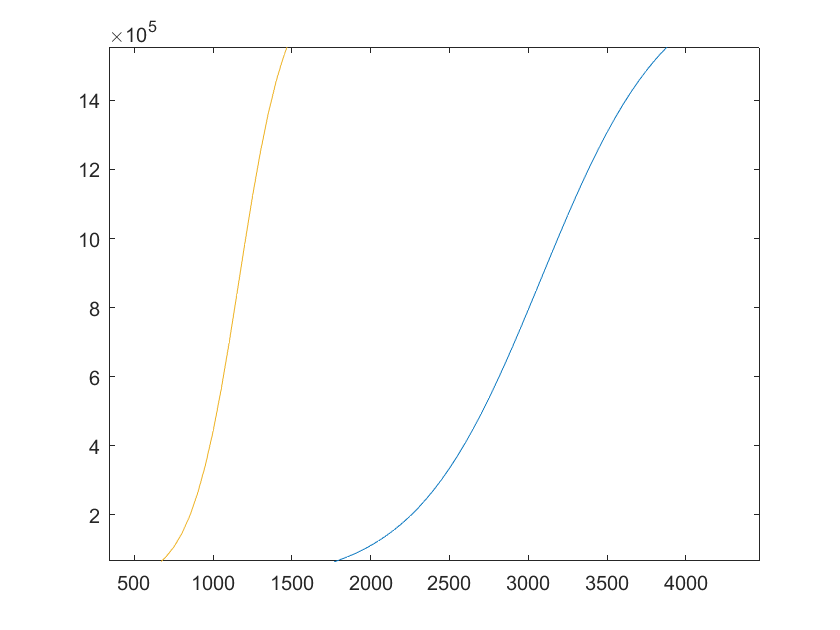

i=1:1/100*m2:m2; nt = K ./ ( 1 + exp( pm.a-pm.b*(0.9*i) ) );
plot(i,nt); hold on;
plot([1,pm.m2],[K,K]); text(pm.m1,fxn(pm.m1,pm),'mature')

xlim([339 4471])
ylim([66717 1554320])


syms a b c
eqn1 = pm.n0==-a/(0+b)+c;
eqn2 = 0.95*pm.n1==-a/(pm.m1+b)+c;
eqn3 = 0.15*pm.n1==-a/(0.1*pm.m1+b)+c;
[a b c]=solve(eqn1,eqn2,eqn3,a,b,c)
x=1:5000;y=vpa(-a./(x+b)+c);plot(x,y)